**Pb 2.** Evaluati spline-ul pe o multime de puncte, daca se dau nodurile, punctele si coeficientii.

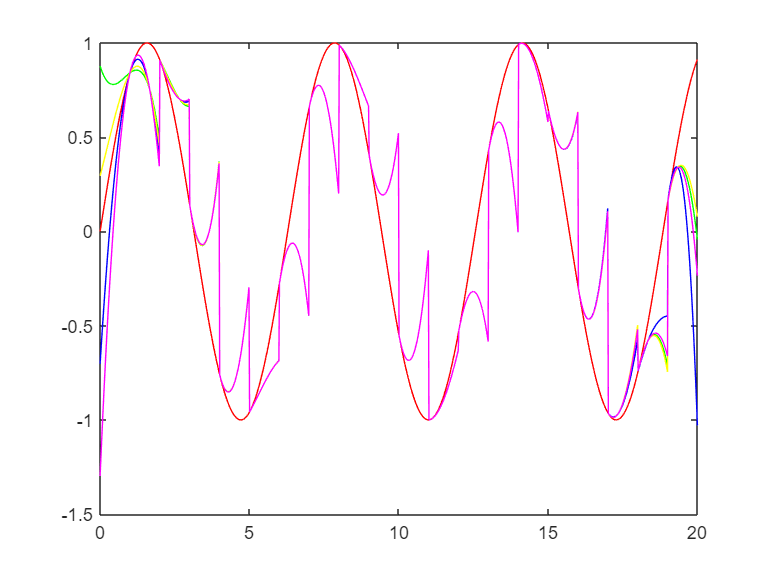

x = [1 : 20];

f = sin(x);
fderiv = cos(x);

tmp = linspace(0, 20, 1000);
plot(tmp, sin(tmp), 'r');
hold on;

% complete - albastru
[a, b, c, d] = calculate_spline(x, f, 0, fderiv);
yy = evaluate_spline(x, a, b, c, d, tmp);
plot(tmp, yy, 'b');

% match second derivates - verde
[a, b, c, d] = calculate_spline(x, f, 1, fderiv);
yy = evaluate_spline(x, a, b, c, d, tmp);
plot(tmp, yy, 'g');

% natural - galben
[a, b, c, d] = calculate_spline(x, f, 2, fderiv);
yy = evaluate_spline(x, a, b, c, d, tmp);
plot(tmp, yy, 'y');

% not a knot - magenta
[a, b, c, d] = calculate_spline(x, f, 3, fderiv);
yy = evaluate_spline(x, a, b, c, d, tmp);
plot(tmp, yy, 'm');
hold off;

**Pb 3.** Desenati o curba spline cubica parametrica ce trece printr-o multime de puncte date.

x = [1, 2, 4, 6, 8];
y = [2, 3, 1, 4, 2];

% coeficienti spline
t = 1:length(x);
ts = 1:0.1:length(x);
spline_x = spline(t, x, ts)

spline_x =     1.0000    1.0194    1.0600    1.1206    1.2000    1.2969    1.4100    1.5381    1.6800    1.8344    2.0000    2.1756    2.3600    2.5519    2.7500    2.9531    3.1600    3.3694    3.5800    3.7906    4.0000    4.2071    4.4120    4.6149    4.8160    5.0156    5.2140    5.4114    5.6080    5.8041    6.0000    6.1959    6.3920    6.5886    6.7860    6.9844    7.1840    7.3851    7.5880    7.7929    8.0000


spline_y = spline(t, y, ts)

spline_y =     2.0000    2.5913    3.0400    3.3588    3.5600    3.6562    3.6600    3.5838    3.4400    3.2413    3.0000    2.7287    2.4400    2.1463    1.8600    1.5938    1.3600    1.1712    1.0400    0.9787    1.0000    1.1117    1.3040    1.5622    1.8720    2.2188    2.5880    2.9653    3.3360    3.6857    4.0000    4.2642    4.4640    4.5847    4.6120    4.5312    4.3280    3.9877    3.4960    2.8382    2.0000


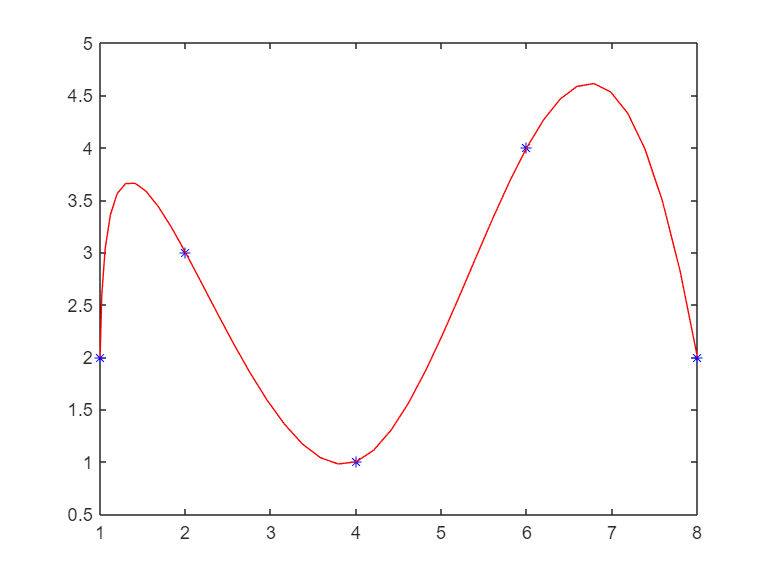


plot(x, y, 'b*');  % punctele
hold on;
plot(spline_x, spline_y, 'r-');  % curba spline
hold off;